## Controls Systems Textbook Example 10.6

### Reset matlab environment

clearvars
close all
clc
s = tf('s');

### Specs: $e_{ss}\text{ for step}=0,\ P.O.\le20$


$$G(s)=\frac{1}{(s+0.5)(s+2)}\\
G_C(s)=K_P+\frac{K_I}{s}=K_P\frac{s_+K_I/K_P}{s}$$


G = 1 / ((s + .5) * (s + 2));   % type 0

### Design of a PI compensator

Your can place your zero ($\frac{K_I}{K_P}$) wherever you want; however, a general rules of thumbs is to place it to cancel the right most dominent pole.


$$G_C(s)=K_P\frac{s+0.5}{s}$$


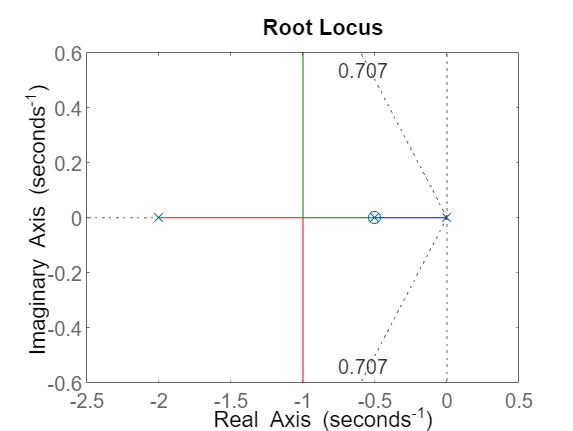

G_C = (s + .5) / s;
rlocus(G * G_C), sgrid(.707, 0)

We choose a gain K_P to a slightly higher damping in order to meet the percent overshoot specification.

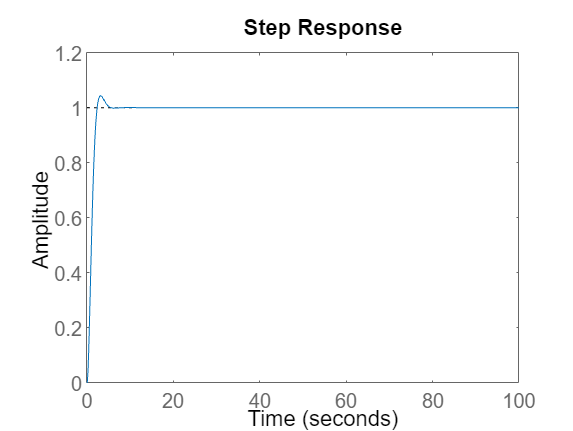

K_P = 2;
T = feedback(K_P * G_C * G, 1);
step(T, 100)

stepinfo(T)

ans = struct with fields:
         RiseTime: 1.5195
    TransientTime: 4.2163
     SettlingTime: 4.2163
      SettlingMin: 0.9034
      SettlingMax: 1.0432
        Overshoot: 4.3210
       Undershoot: 0
             Peak: 1.0432
         PeakTime: 3.1315
